clear; clc; close all;

filename = '/home/kuhu/Documents/eclectronics/mp1/LTspice/kuhu-miniproject1.txt';

fid = fopen(filename, 'r');

if fid == -1
    error('Could not open file: %s', filename);
end


%% Read Monte Carlo Runs
periods = [];
t = [];
v = [];

while ~feof(fid)
    line = fgetl(fid);

    % Start of a new LTspice run
    if contains(line, 'Step Information')

        % Calculate period from previous run
        if ~isempty(t)
            periods(end+1) = findPeriod(t, v);
        end

        t = [];
        v = [];

    else
        % Read time and voltage
        nums = sscanf(line, '%f %f');

        if length(nums) == 2
            t(end+1) = nums(1);
            v(end+1) = nums(2);
        end
    end
end

% Process final run
if ~isempty(t)
    periods(end+1) = findPeriod(t, v);
end

fclose(fid);

% Remove failed measurements
periods = periods(~isnan(periods));


%% Results
fprintf('Number of runs: %d\n', length(periods));

Number of runs: 250


fprintf('Mean period: %.4f s\n', mean(periods));

Mean period: 0.9856 s


fprintf('Minimum period: %.4f s\n', min(periods));

Minimum period: 0.9339 s


fprintf('Maximum period: %.4f s\n', max(periods));

Maximum period: 1.0314 s


fprintf('Standard deviation: %.4f s\n', std(periods));

Standard deviation: 0.0183 s



fprintf('Runs within 0.9-1.1 s: %d / %d\n', ...
    sum(periods >= 0.9 & periods <= 1.1), length(periods));

Runs within 0.9-1.1 s: 250 / 250


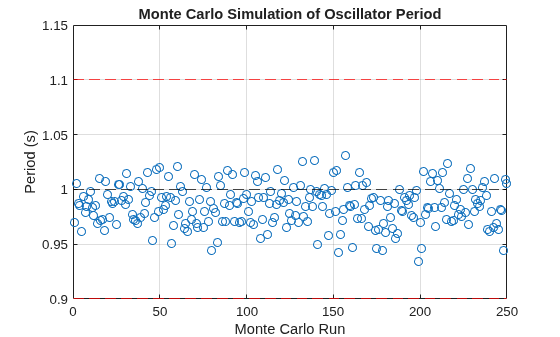



%% Monte Carlo Plot
figure;

plot(periods, 'o');
yline(0.9, '--r');
yline(1.0, '--k');
yline(1.1, '--r');

xlabel('Monte Carlo Run');
ylabel('Period (s)');
title('Monte Carlo Simulation of Oscillator Period');
grid on;

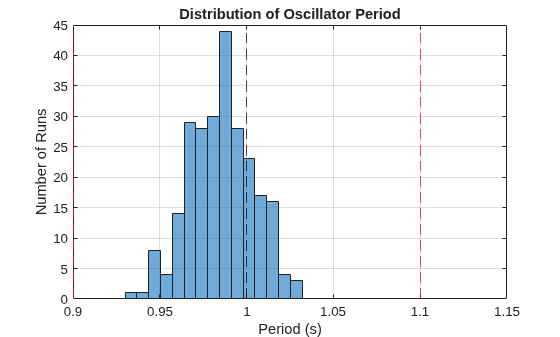



%% Histogram
figure;

histogram(periods, 15);
xline(0.9, '--r');
xline(1.0, '--k');
xline(1.1, '--r');

xlabel('Period (s)');
ylabel('Number of Runs');
title('Distribution of Oscillator Period');
grid on;



%% Find Period
function T = findPeriod(t, v)

    threshold = 1.65;

    % Find rising edges
    edges = find(v(1:end-1) < threshold & ...
                 v(2:end) >= threshold);

    crossingTimes = t(edges);

    % Remove duplicate crossings
    goodEdges = [true, diff(crossingTimes) > 0.2];
    crossingTimes = crossingTimes(goodEdges);

    % Period = time between last two rising edges
    if length(crossingTimes) >= 2
        T = crossingTimes(end) - crossingTimes(end-1);
    else
        T = NaN;
    end
end